# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 7.6.2 Windowing Functions

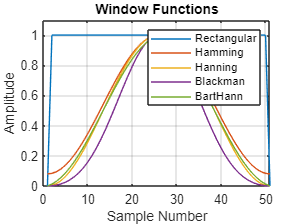

% Set the number of window samples
ns = 51;

% Get the window coefficients
win0 = ones(ns,1); win0(1) = 0; win0(end) = 0;
win1 = hamming(ns);
win2 = hanning(ns);
win3 = blackman(ns-1);
win4 = barthann(ns-1);

% Plot the window coefficients
figure; plot(win0); hold on;
plot(win1); plot(win2); plot(win3); plot(win4);
xlabel('Sample Number')
ylabel('Amplitude')
title('Window Functions')
legend('Rectangular', 'Hamming', 'Hanning', 'Blackman', 'BartHann');
grid on
yticks([0, 0.2, 0.4, 0.6, 0.8, 1.0])
ylim([0 1.1])
xlim([0 51])

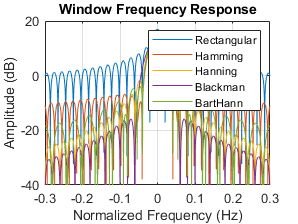



% Calcualte the frequency response of each window
nfft = 32768;
wf0 = fftshift(abs(fft(win0, nfft)));
wf1 = fftshift(abs(fft(win1, nfft)));
wf2 = fftshift(abs(fft(win2, nfft)));
wf3 = fftshift(abs(fft(win3, nfft)));
wf4 = fftshift(abs(fft(win4, nfft)));

% Set the normalized frequency
f = linspace(-0.5, 0.5, nfft);

% Plot the frequency responses
figure; plot(f, 10*log10(wf0), '-'); hold on
plot(f, 10*log10(wf1), '-'); plot(f, 10*log10(wf2), '-'); plot(f, 10*log10(wf3), '-'); plot(f, 10*log10(wf4), '-');
ylim([-40 20])
xlim([-0.3, 0.3])
xticks([-0.3, -0.2, -0.1, 0, 0.1, 0.2, 0.3])
xlabel('Normalized Frequency (Hz)')
ylabel('Amplitude (dB)')
legend('Rectangular', 'Hamming', 'Hanning', 'Blackman', 'BartHann');
title('Window Frequency Response')
grid on

function out = blackman(L)
for n = 0:1:L
    out(n+1) = 0.42 - 0.5*cos(2*pi*n/L) + 0.08*cos(4*pi*n/L);
end
end

function out = barthann(L)
for n = 0:1:L
    out(n+1) = 0.62 - 0.48 * abs(n/(L-1*0) - 0.5) + 0.38*cos(2*pi * abs(n/(L-1*0) - 0.5));
end
end